# ME 507 - Inverted Pendulum Control

**Author: Jake Vormbaum**

**Date Created: 10/03/2023**

**Date Modified: 10/04/2023**

**Description:** 

- **pendulum_script.mlx**: This script contains the inputs as well as plots the results

- **pendulum_model.slx:** This model contains the block diagram of the control loop

clc;
clear;
close;

syms L m_p theta theta_dot x_dot m_c F g delta
A = [m_c + m_p m_p*L*cos(theta)
  m_p*L*cos(theta) m_p*L^2]

$$A = \left(\begin{array}{cc} m_{c}+m_{p} & L\,m_{p}\,\cos\left(\theta \right)\\ L\,m_{p}\,\cos\left(\theta \right) & L^{2}\,m_{p} \end{array}\right)$$

B = [F+m_p*L*theta_dot^2*sin(theta)-delta*x_dot
     m_p*L*g*sin(theta)]

$$B = \left(\begin{array}{c} L\,m_{p}\,\sin\left(\theta \right)\,{\dot{\theta }}^{2}+F-\delta \,\dot{x}\\ L\,g\,m_{p}\,\sin\left(\theta \right) \end{array}\right)$$

x = simplify(A^-1*B)

$$x = \begin{array}{l} \left(\begin{array}{c} \frac{L\,m_{p}\,\sin\left(\theta \right)\,{\dot{\theta }}^{2}+F-\delta \,\dot{x}-g\,m_{p}\,\cos\left(\theta \right)\,\sin\left(\theta \right)}{\sigma_{1}}\\ \frac{-L\,m_{p}\,\cos\left(\theta \right)\,\sin\left(\theta \right)\,{\dot{\theta }}^{2}-F\,\cos\left(\theta \right)+\delta \,\dot{x}\,\cos\left(\theta \right)+g\,m_{c}\,\sin\left(\theta \right)+g\,m_{p}\,\sin\left(\theta \right)}{L\,\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-m_{p}\,{\cos\left(\theta \right)}^{2}+m_{c}+m_{p} \end{array}$$

var = simplify(subs(x,[sin(theta),cos(theta),theta_dot],[theta,1,0]))

$$var = \left(\begin{array}{c} -\frac{\delta \,\dot{x}-F+g\,m_{p}\,\theta }{m_{c}}\\ \frac{\delta \,\dot{x}-F+g\,m_{c}\,\theta +g\,m_{p}\,\theta }{L\,m_{c}} \end{array}\right)$$

A = [0     1                0                     0
     0     -delta/m_c        -g*m_p/m_c              0
     0     0                0                     1
     0,    delta/(L*m_c)     g*(m_c+m_p)/(L*m_c)      0]

$$A = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & -\frac{\delta }{m_{c}} & -\frac{g\,m_{p}}{m_{c}} & 0\\ 0 & 0 & 0 & 1\\ 0 & \frac{\delta }{L\,m_{c}} & \frac{g\,\left(m_{c}+m_{p}\right)}{L\,m_{c}} & 0 \end{array}\right)$$

## Define the Parameters

### Physical

m_c = 0.15;          % Mass of the cart
m_p = 0.3;          % Mass of the pendulum
g = 9.81;        % Earth gravity
L = 0.5;           % Length of the pendulum
delta = 0;       % Damping of the cart
b_rolling = 0.1;
b_pitching = 0.1;

### Motors

stall_T_datasheet = 7.0;                % Motor stall torque [kgf-cm]
stall_T = 2*stall_T_datasheet*(g/100)   % Motor stall torque [N-m]

stall_T = 1.3734

## Define the Matrices

A = [0     1                0                     0
     0     -delta/m_c        -g*m_p/m_c              0
     0     0                0                     1
     0,    delta/(L*m_c)     g*(m_c+m_p)/(L*m_c)      0];
B = [0
     1/m_c
     0
     -1/(L*m_c)];

## Output

C = [1, 0, 0, 0
     0, 1, 0, 0
     0, 0, 1, 0
     0, 0, 0, 1];
D = [0; 0; 0; 0];

## Build the System

sys = ss(A,B,C,D)

sys =
 
  A = 
           x1      x2      x3      x4
   x1       0       1       0       0
   x2       0       0  -19.62       0
   x3       0       0       0       1
   x4       0       0   58.86       0
 
  B = 
           u1
   x1       0
   x2   6.667
   x3       0
   x4  -13.33
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
   y3   0   0   1   0
   y4   0   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
   y4   0
 
Continuous-time state-space model.


x_0 = [0;    0*pi/180;   0;  0];

## Analyze the System

P = pole(sys);
T = tf(sys)

T =
 
  From input to output...
       6.667 s^2 + 5.921e-15 s - 130.8
   1:  -------------------------------
       s^4 - 8.882e-16 s^3 - 58.86 s^2
 
       6.667 s^2 + 5.921e-15 s - 130.8
   2:  -------------------------------
        s^3 - 8.882e-16 s^2 - 58.86 s
 
                -13.33
   3:  -------------------------
       s^2 - 8.882e-16 s - 58.86
 
               -13.33 s
   4:  -------------------------
       s^2 - 8.882e-16 s - 58.86
 
Continuous-time transfer function.


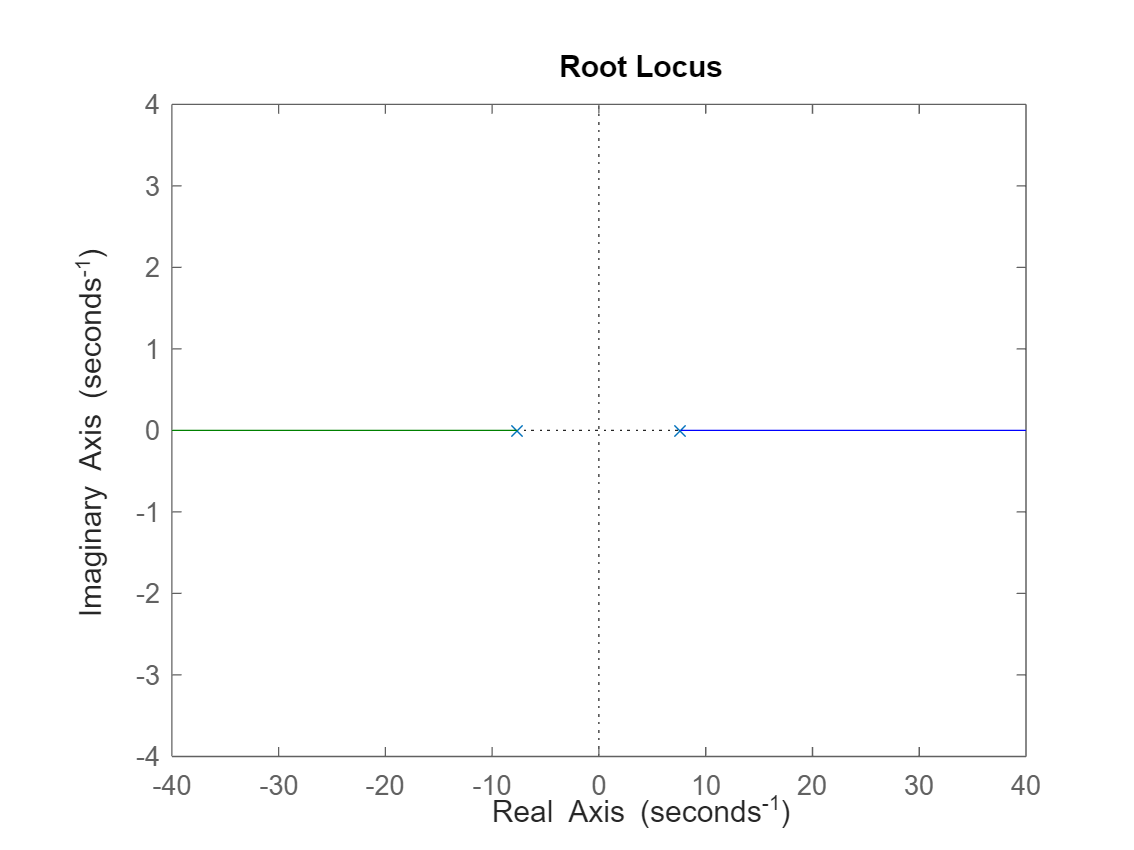

[b,a] = ss2tf(A,B,C,D);
rlocus(T(3))

rank(ctrb(A,B))

ans = 4

%rltool(T(3))

## Targets and Disturbance

target_angle = 0.0*(pi/180);        % radians
period = 20;                        % s
pulse_width = 1;                    %
disturbance = 0.75;                 % N-m

## Controller

K_p_pitch = 15.0;   % Proportional gain
K_i_pitch = 5.0;    % Integral gain

## Run the Model

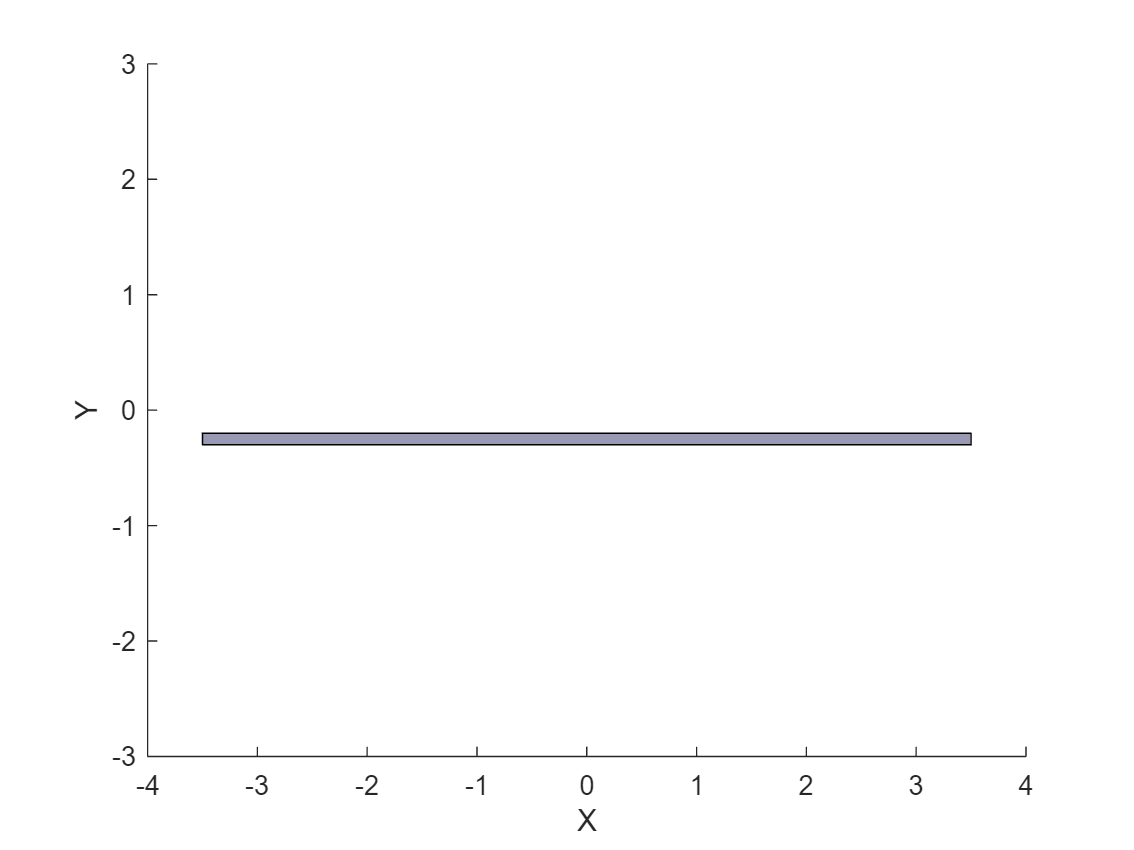

t_stop = 25;
simout = sim("pendulum_model_PI.slx", t_stop);

## Plot Data

### Load Data

load output;

### Read Data

x = simout.x(:,1);
theta = simout.x(:,2)*180/pi;
x_dot = simout.x(:,3);
theta_dot = simout.x(:,4)*60/(2*pi);
theta_ref = out.Data(:,5)*180/pi;
t = out.Time;
torque = simout.u;

### Plot Data

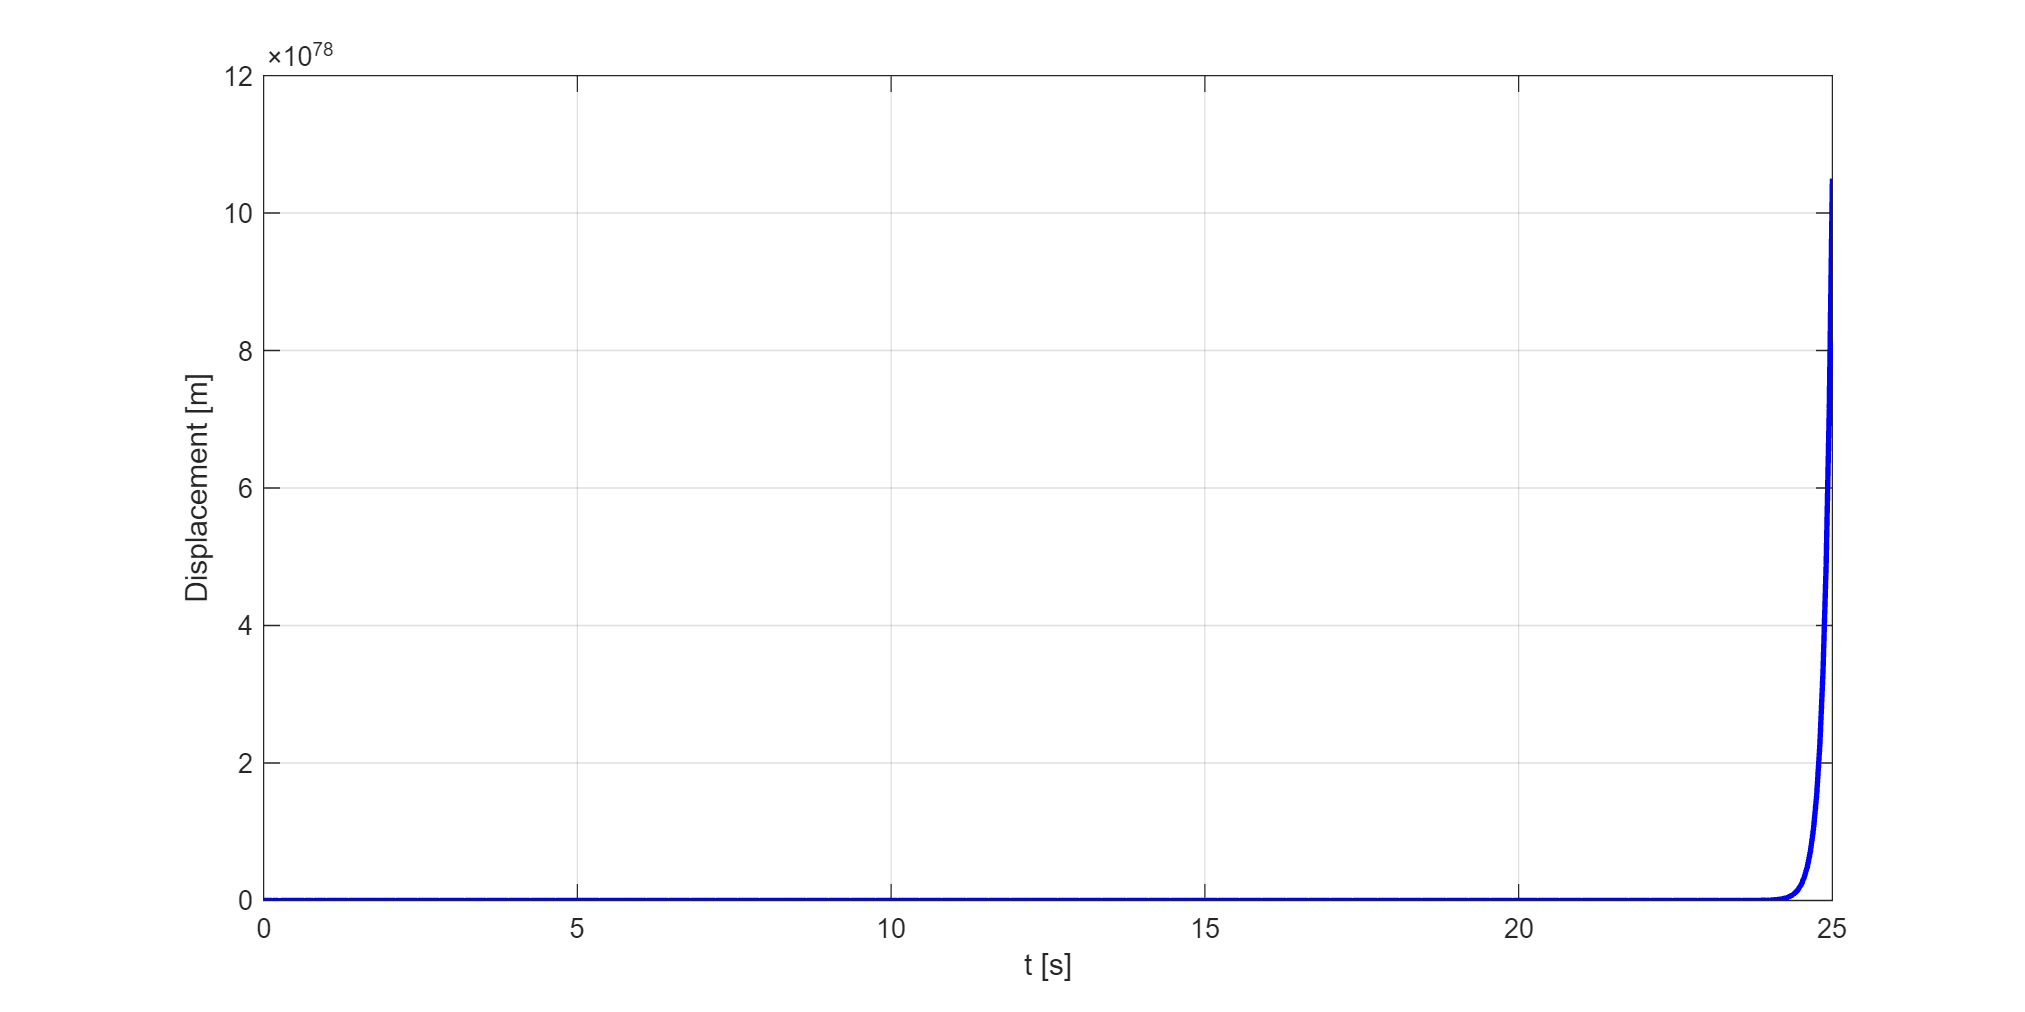

figure('Position',[0 0 1000 500]);
plot(t,x,'b','LineWidth',2); grid on
ylabel('Displacement [m]')
xlabel('t [s]')

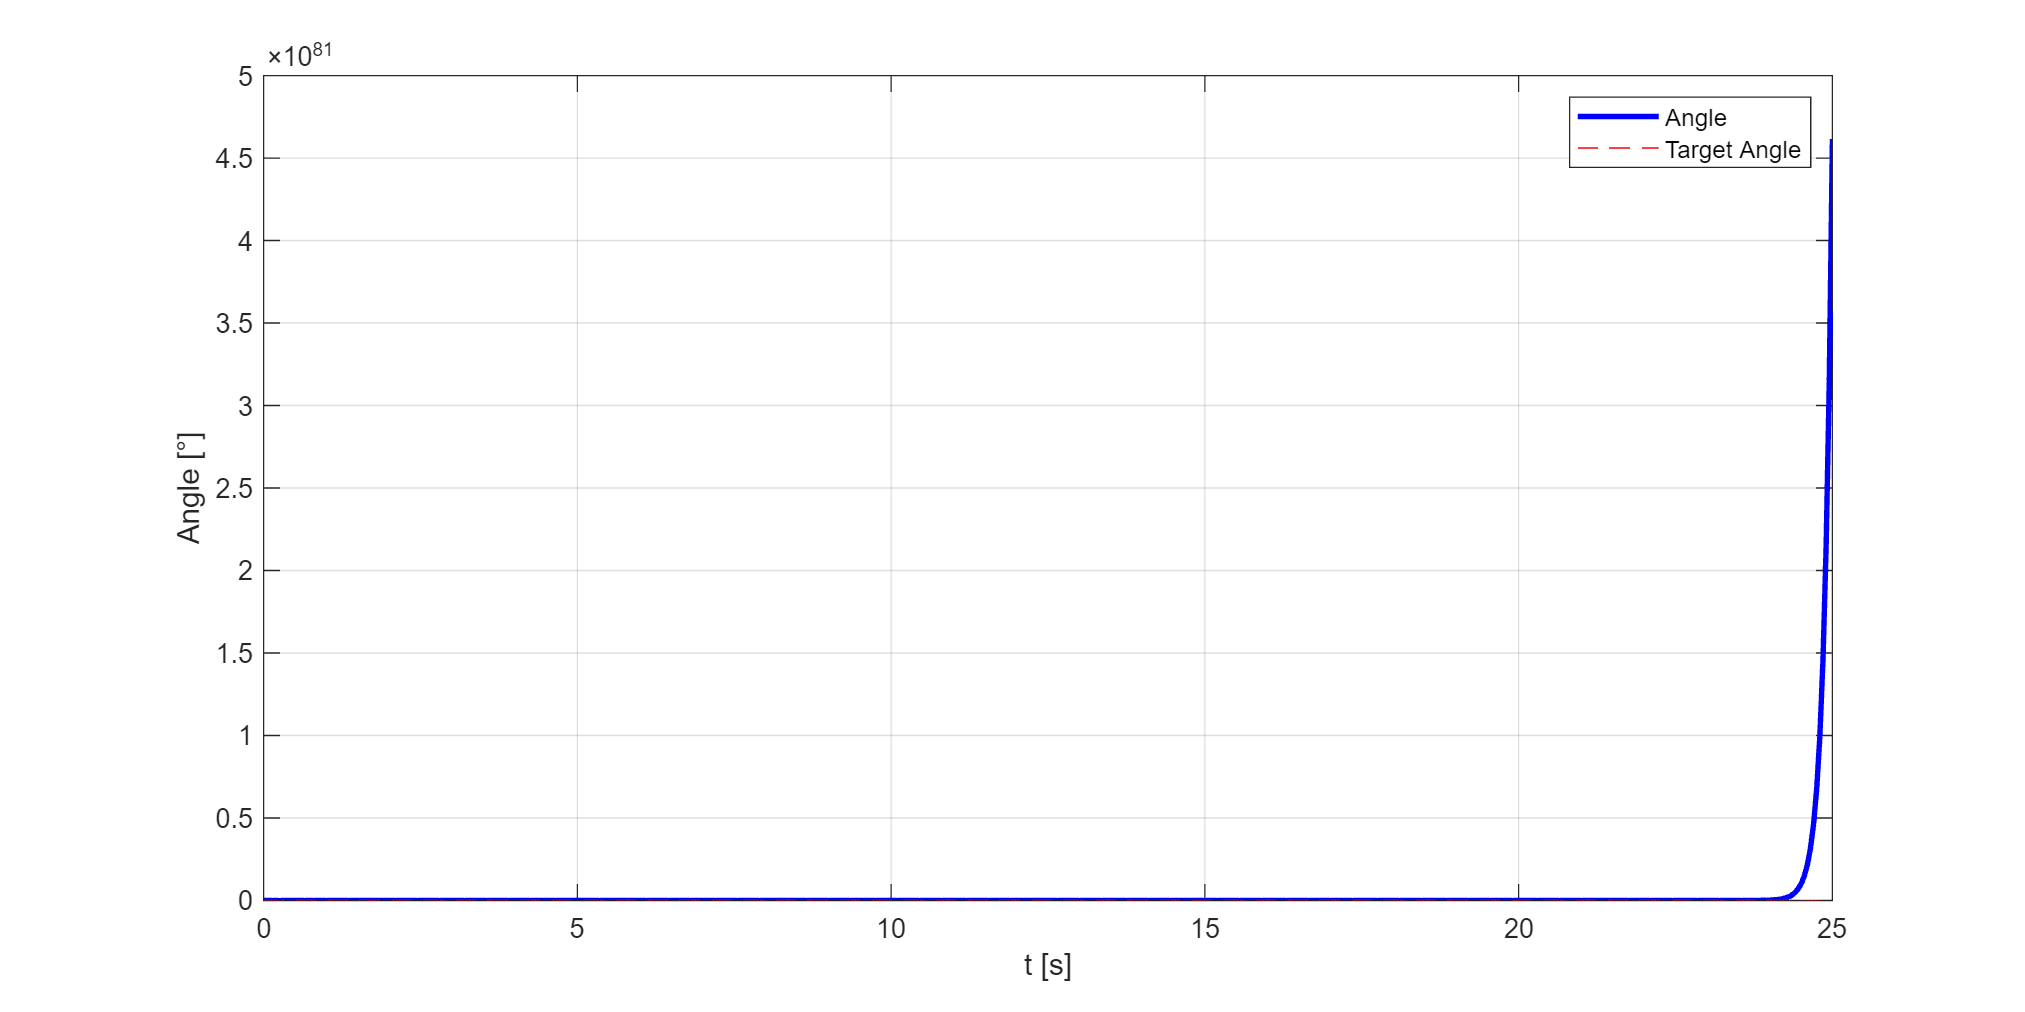

figure('Position',[0 0 1000 500]);
plot(t,theta,'b','LineWidth',2); grid on
hold on
plot(t,theta_ref,'r--')
hold off
ylabel('Angle [°]')
xlabel('t [s]')
legend('Angle','Target Angle')

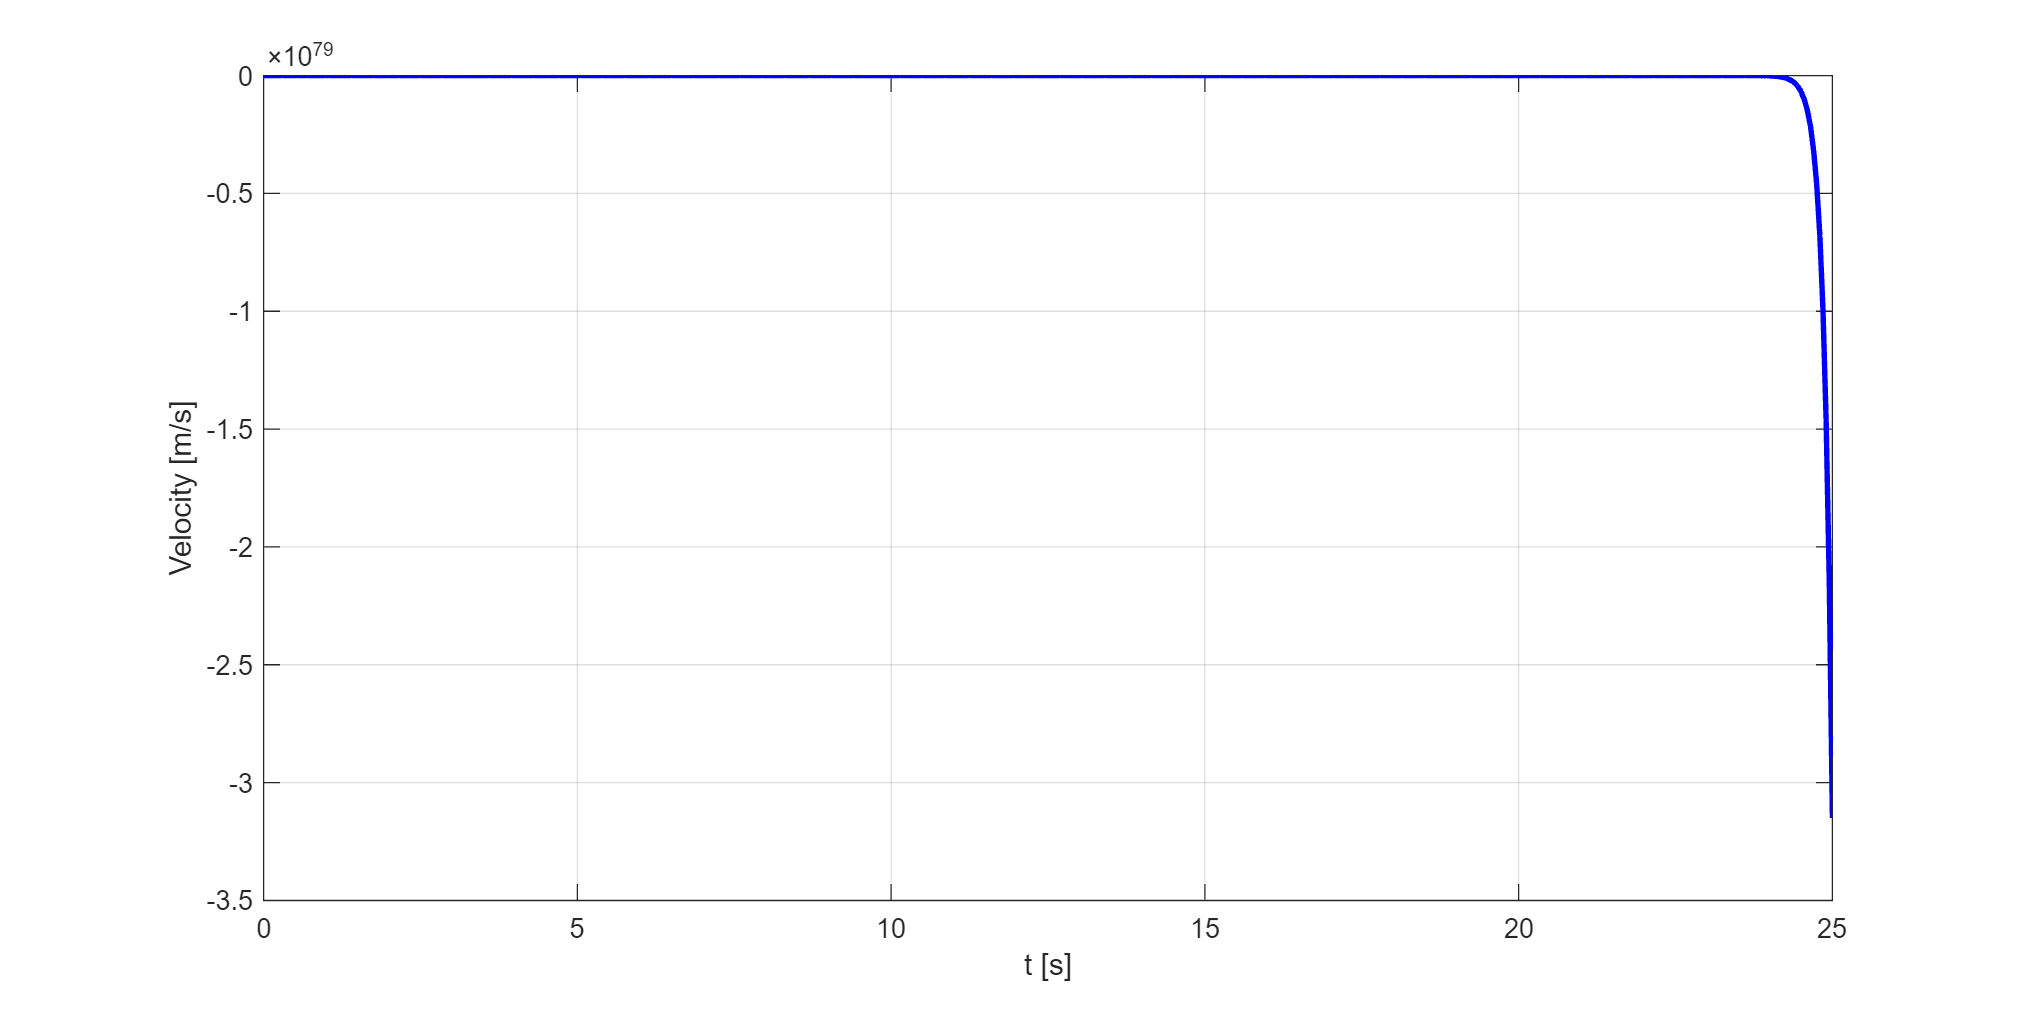

figure('Position',[0 0 1000 500]);
plot(t,x_dot,'b','LineWidth',2); grid on
ylabel('Velocity [m/s]')
xlabel('t [s]')

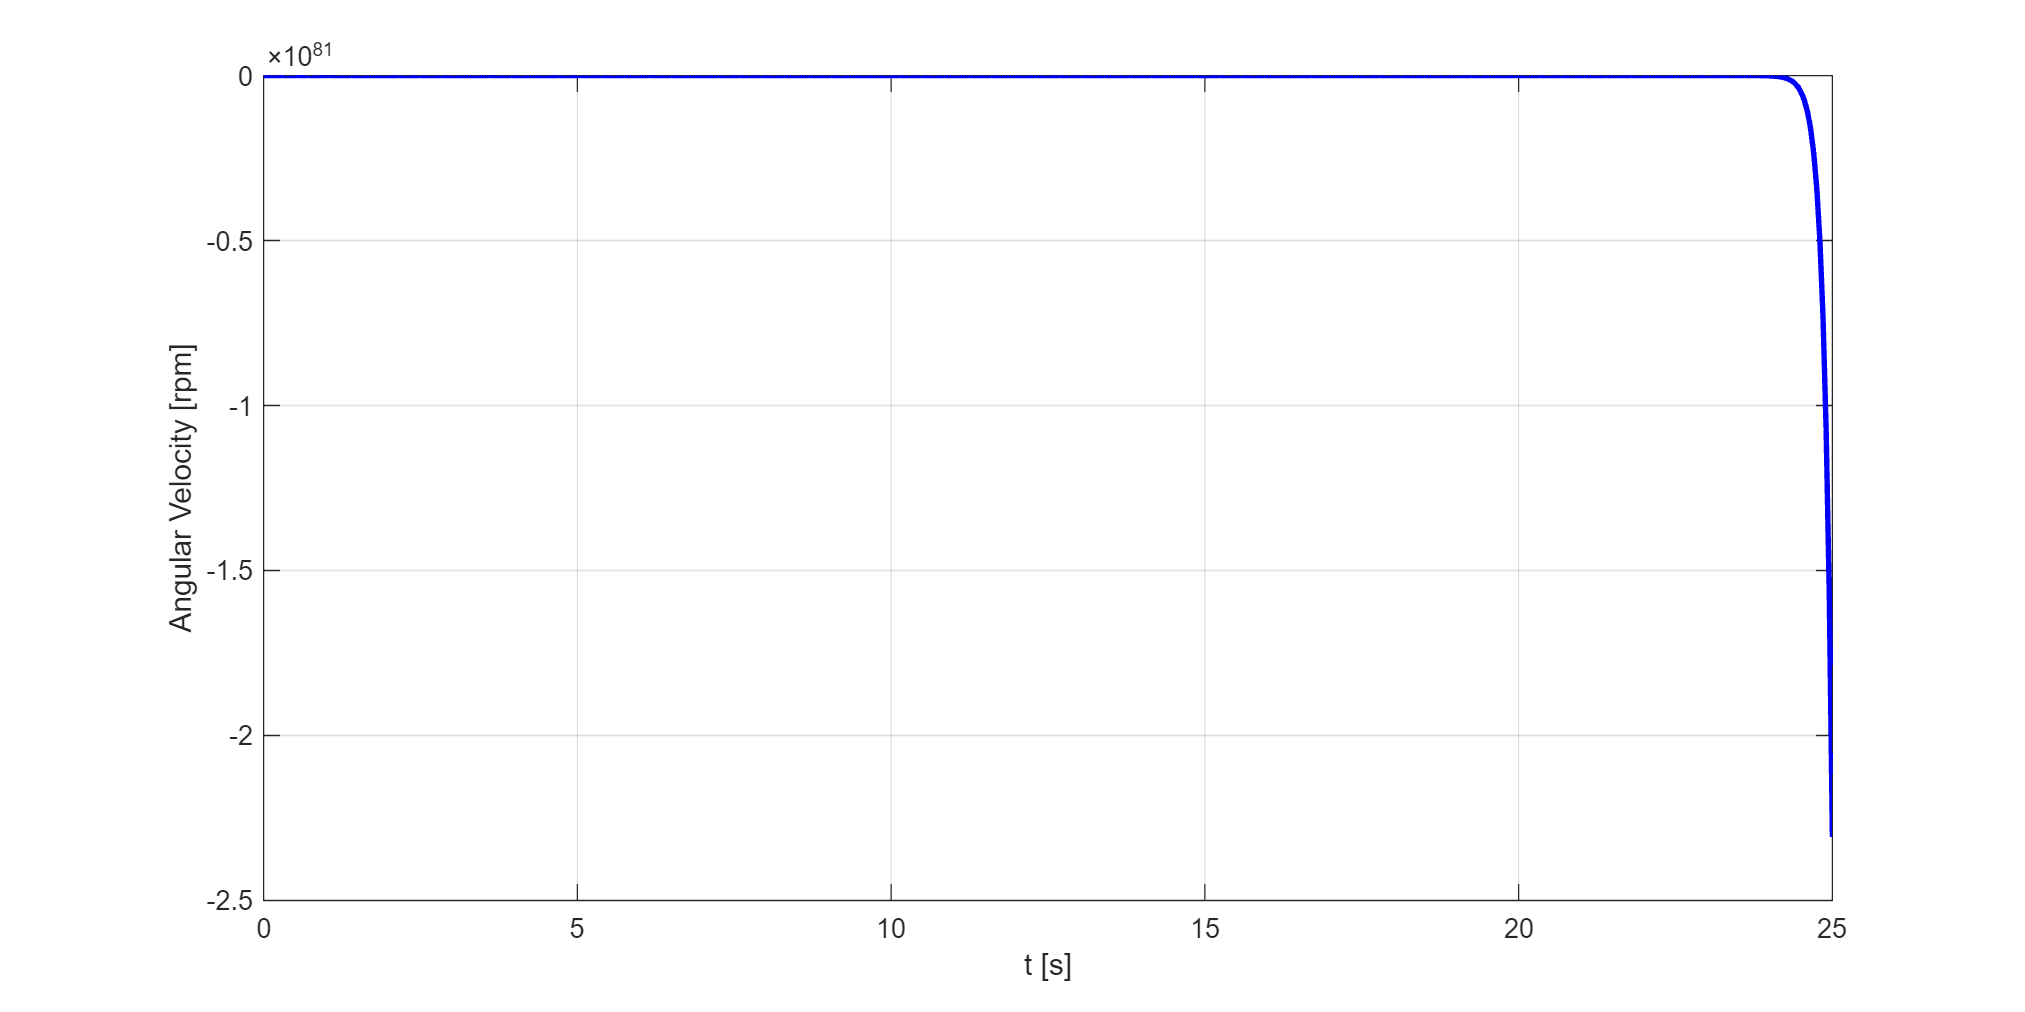

figure('Position',[0 0 1000 500]);
plot(t,theta_dot,'b','LineWidth',2); grid on
ylabel('Angular Velocity [rpm]')
xlabel('t [s]')

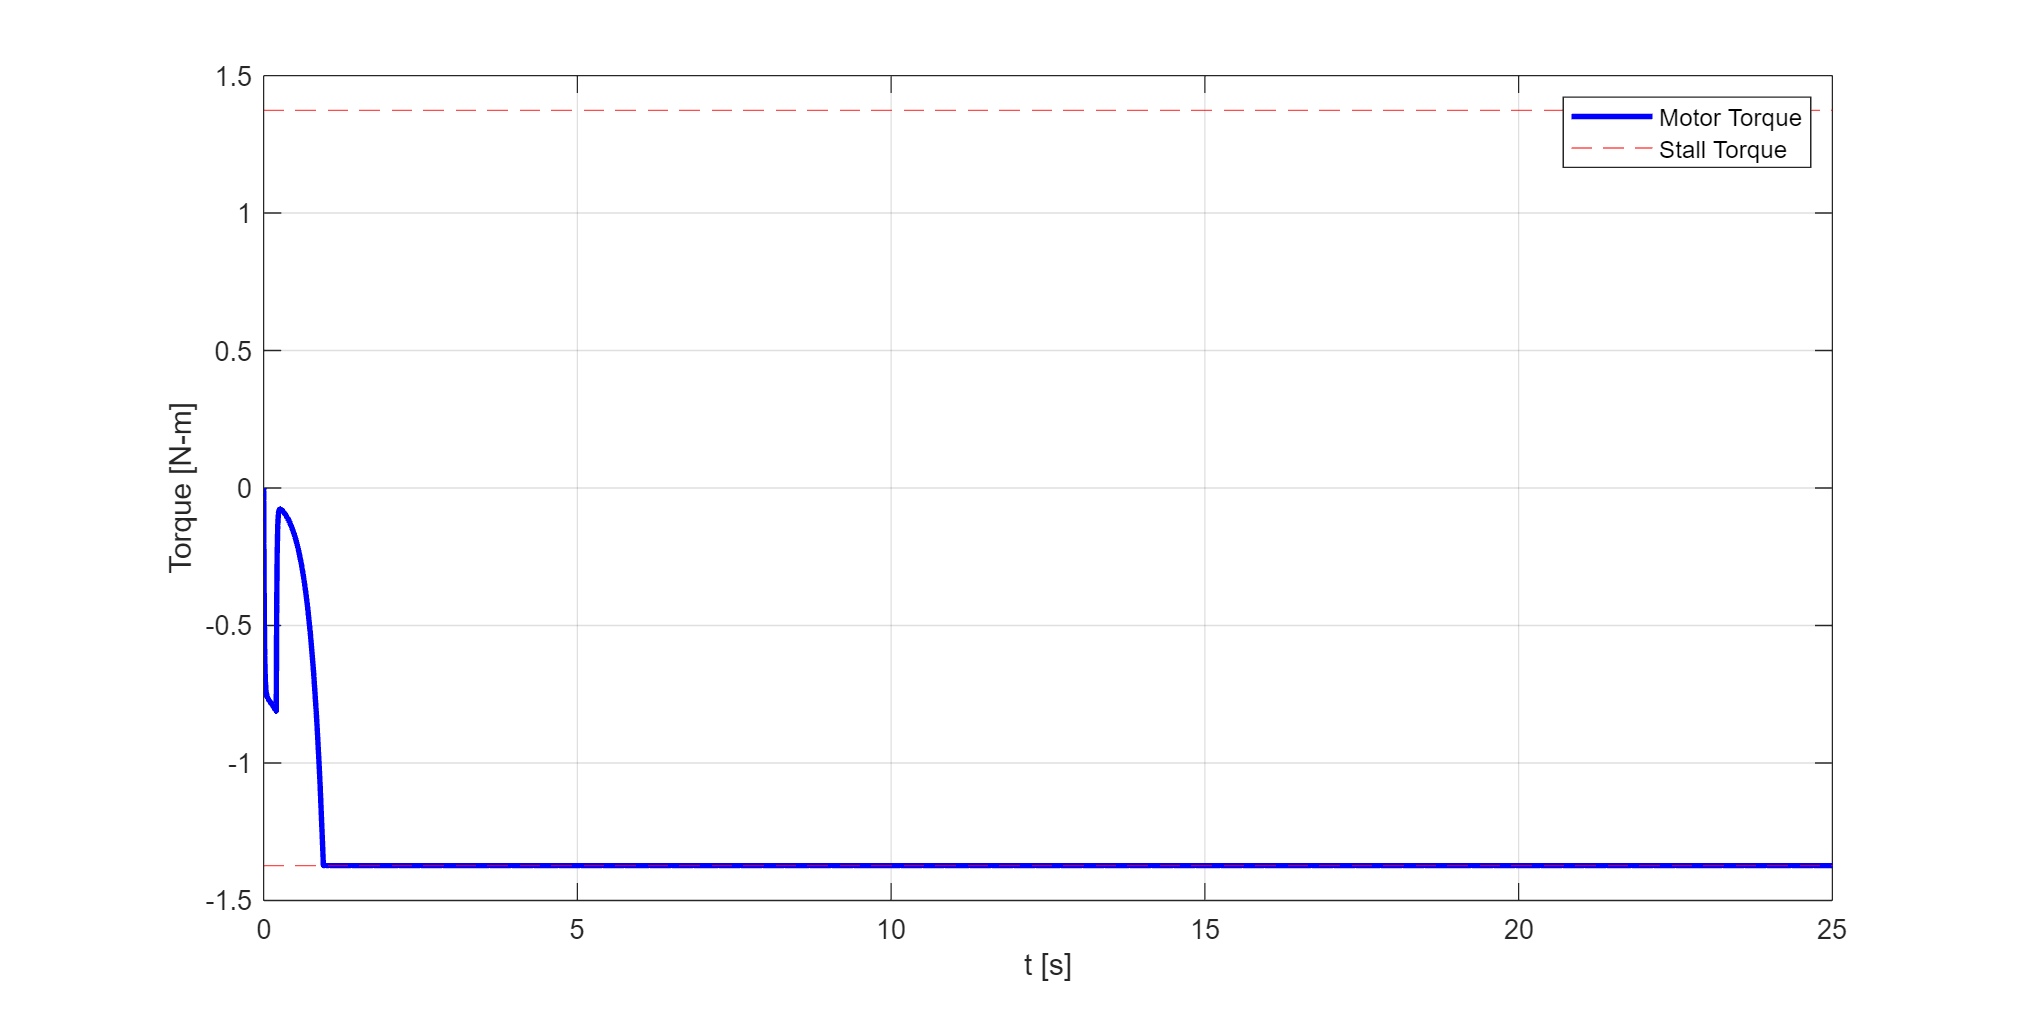


figure('Position',[0 0 1000 500]);
plot(t,torque,'b','LineWidth',2); grid on
hold on
yline(stall_T,'r--')
yline(-stall_T,'r--')
hold off
ylabel('Torque [N-m]')
xlabel('t [s]')
legend('Motor Torque','Stall Torque')

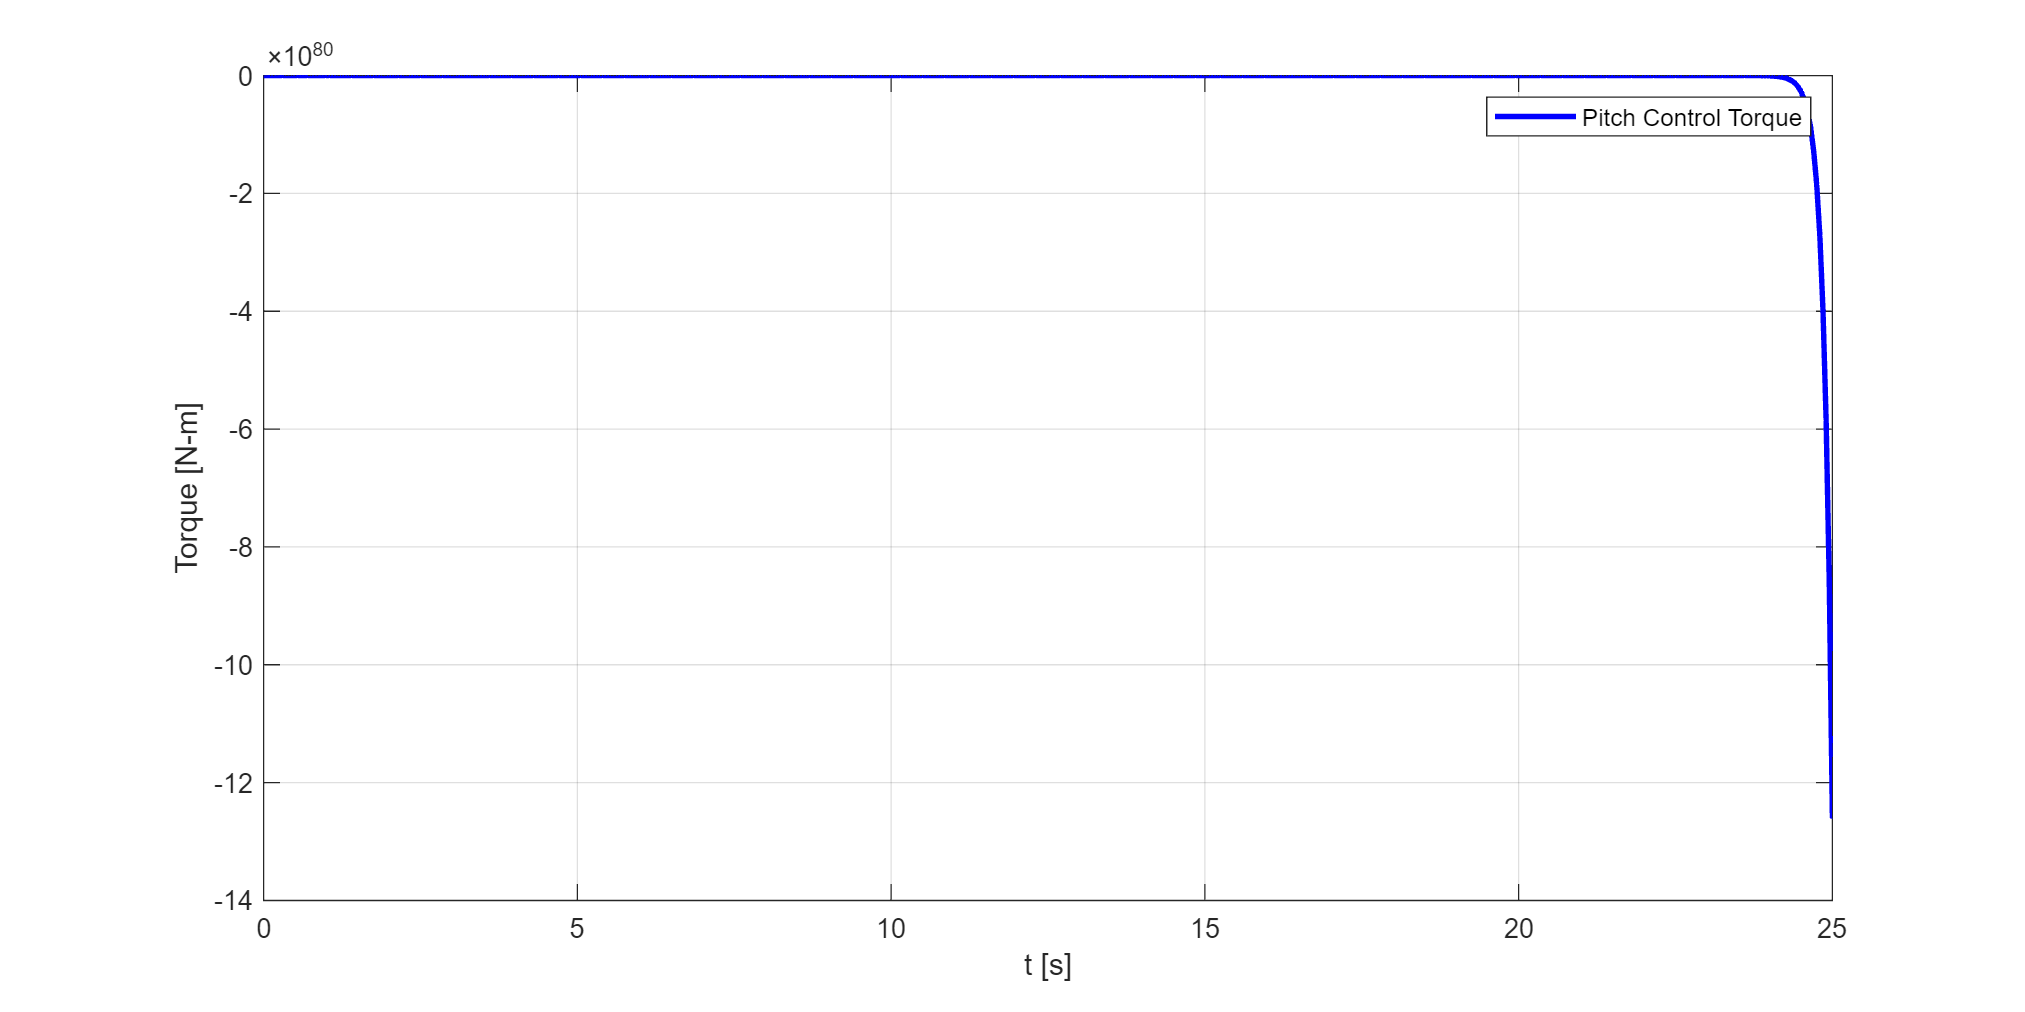

figure('Position',[0 0 1000 500]);
plot(t,simout.pitch_control,'b','LineWidth',2); grid on
ylabel('Torque [N-m]')
xlabel('t [s]')
legend('Pitch Control Torque')